## How to properly tweak envelopes

### The ABC

Focus on the attack first, since the decay and release curves are "inverted" attack, with a range.

Need to define a clean attack that leverages from few micro-secronds (the *anti-glitch* minimum time) to 10 seconds.

In this document we will consider:

global sampling_freq
sampling_freq_khz = 48;
sampling_freq = sampling_freq_khz * 1000;
global atk_min
atk_min = 10;
global atk_max
atk_max = 10 * sampling_freq;
titles = ["Sampling frequency (kHz)" ; "min attack time (ticks)" ; "max attack time (ticks)"];
values = [sampling_freq_khz ; atk_min ; atk_max];
for i = 1:3
    fprintf("%s = %d\n", titles(i), values(i));
end

Sampling frequency (kHz) = 48
min attack time (ticks) = 10
max attack time (ticks) = 480000


Need to design a clean attack envelope, with respect to ear's perception, which is basically logarithmic.

The raw curve is given by the *cincr* function, that increments the amplitude at every tick:


$$A=A_{\max } \;\left(1-e^{-\;\frac{t}{T}} \right)$$


Where:

- $A_{\max } \;$is the maximum amplitude (i.e. 1 for an attack if the volume leverages from 0 to 1

- $t$is the current tick, from 0 to the duration (in samples) of the attack (named *atk* in this study)

- $T$ defines the *aggressivity* of the curve, the lower the more aggressive

Intuitively, for very short attacks, we need a very low value for $T$ and a much bigger for slow attacks:


$$T=\phi \left(\textrm{atk}\right)$$


For example, given $\phi \left(x\right)=x$, the attack curves for different attack durations are:

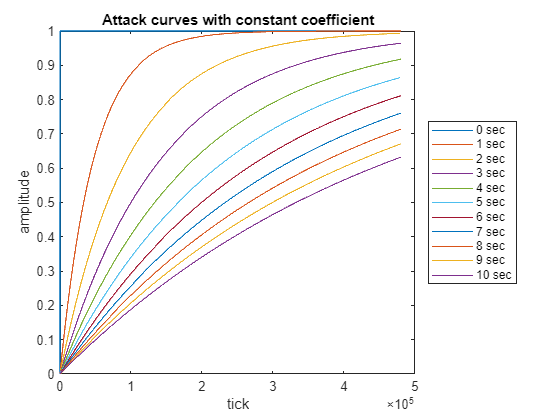

ticks = linspace(0, atk_max, atk_max);
cur = strings(0);
out = [];
for atk_sec = 0:10
    max_tick = max(atk_min, sampling_freq * atk_sec);
    cur(end + 1) = int2str(atk_sec) + " sec";
    out(end + 1, :) = cincr1(ticks, max_tick, 1, max_tick);
end
[nlines, ~] = size(out);
for i = 1:nlines
    plot(out(i, :), 'DisplayName', cur(i));
    hold on;
end
hold off;
legend(cur, 'Location', 'eastoutside');
xlabel('tick');
ylabel('amplitude');
title("Attack curves with constant coefficient");

Clearly, the figure above shows that $T=\phi \left(\mathrm{atk}\right)$ is not a good choice: for long attacks, the curve is to "linear" and does not reach the expected maximum.

### Empirical test with constant value

Preliminary experimentations show that:


$$\phi \left(t\right)=\frac{t}{10}\Rightarrow T=\frac{\mathrm{atk}}{10}\Rightarrow A=A_{\max } \;\left(1-e^{-10\;\frac{t}{\mathrm{atk}}} \right)$$


works pretty well with short attacks, but not that much with longer attacks, because the maximum amplitude reaches too fast.

Let's experiment with different constant values:

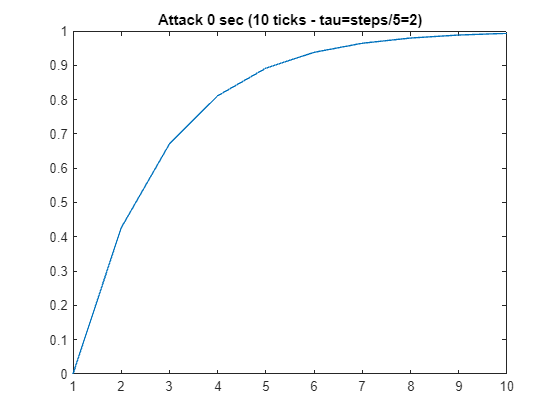

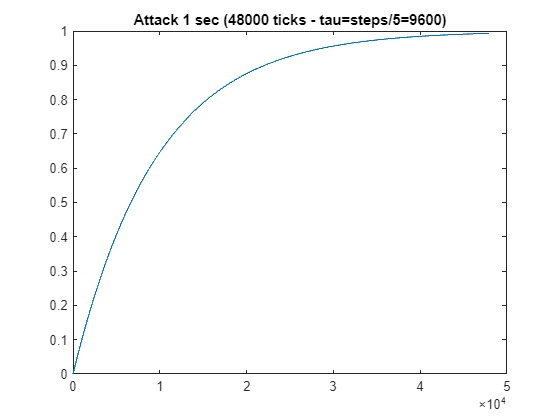

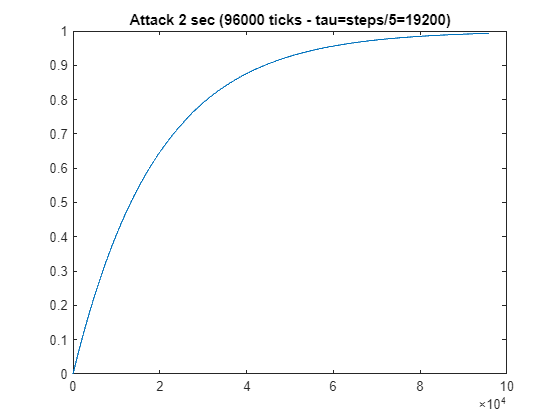

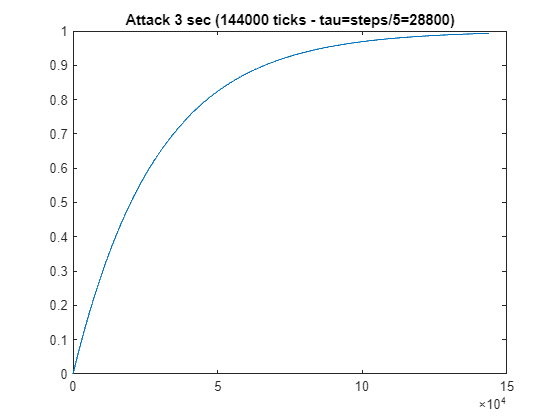

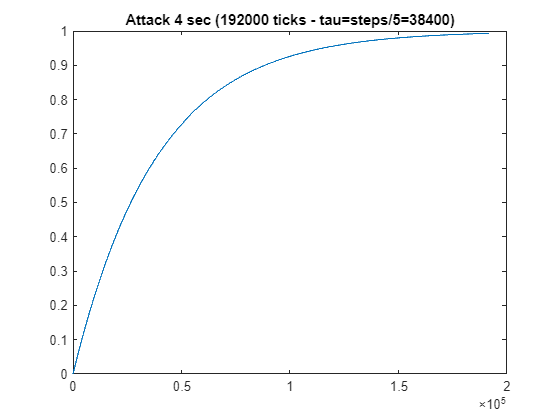

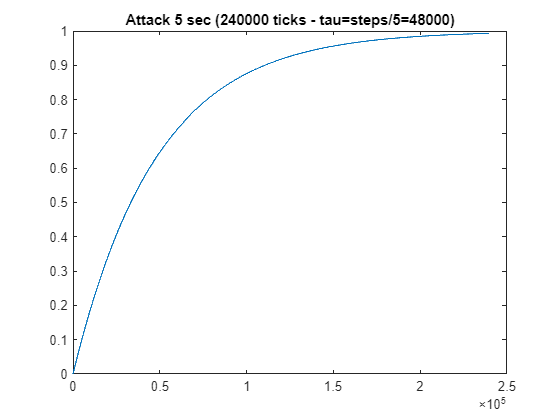

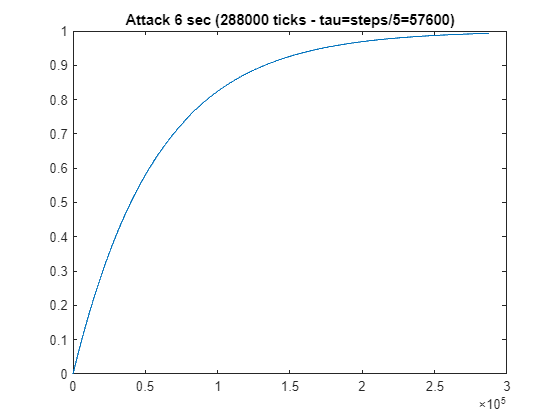

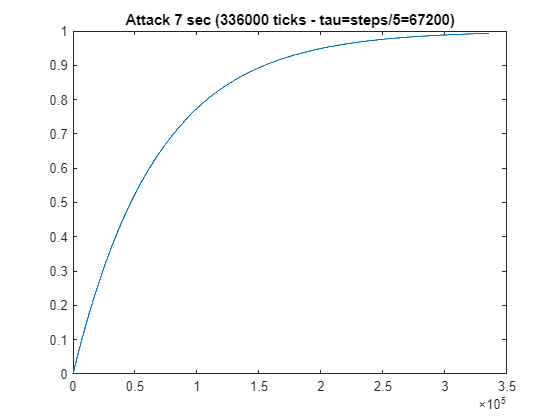

consts = [5 ; 5 ; 5 ; 5 ; 5 ; 5 ; 5 ; 5 ; 5 ; 5 ; 5];
for atk_sec = 0:10
    max_tick = max(atk_min, sampling_freq * atk_sec);
    tau = max_tick / consts(atk_sec + 1);
    ticks = linspace(0, max_tick, max_tick);
    figure;
    xlabel('tick');
    ylabel('amplitude');
    plot(cincr1(ticks, tau, 1, max_tick));
    title(['Attack ', int2str(atk_sec), ' sec (', int2str(max_tick), ' ticks - tau=steps/', int2str(consts(atk_sec+1)), '=', int2str(tau), ')']);
end

### Perceptive considerations

Considering ampitudes in this scope implies thinking in subtracting decibels rather than adding. In other words, an amplitude of 1 is the maximum volume that can be reached, whereas 0 means "removing enough dB to get an unperceptible sound".

Empirically, **-40dB** is a good threshold to consider that the output is almost silent.

We want to get attacks that:

- Grow very fast at the beggining

- Become much flatter when reaching the asymptotic value of 1

We may consider **-6dB** and **-3dB** as well-known remarkable points to tune the attack curve.

Practically, it means:

- Identifying noticeable ticks $t_0$, $t_1$... and the amount of decibels $d_i$ to remove from the maximum amplitude $A_{\max }$

- Defining the target amplitude at each point: $A_i \approx A_{\max } \;{10}^{-\;\frac{d_i }{20}}$, where $d_i$ is the number of expected decibels lost

dbs = [40 ; 6 ; 3 ; 0.01];
[n, ~] = size(dbs);
for i = 1:n
    fprintf("loss=%f : amplitude=%f\n", dbs(i), db_loss(dbs(i), 1));
end

loss=40.000000 : amplitude=0.010000
loss=6.000000 : amplitude=0.501187
loss=3.000000 : amplitude=0.707946
loss=0.010000 : amplitude=0.998849


For a given target amplitude $A$ that must be reached at a given tick $t$, one can compute the corresponding value of $T$: 


$$A=A_{\max } \;\left(1-e^{-\;\frac{t}{T}} \right)\Rightarrow \;T=\frac{-t}{\ln \left(1-\frac{A}{A_{\max } }\right)}$$


Empirically, we saw that $\phi \left(t\right)=\frac{t}{5}$ gives a pretty good result.

TODO: complete explaining why so that we can adjust a fine parameter.

Let's observe the behavior with a constraint of -3dBs at a quarter of the attack

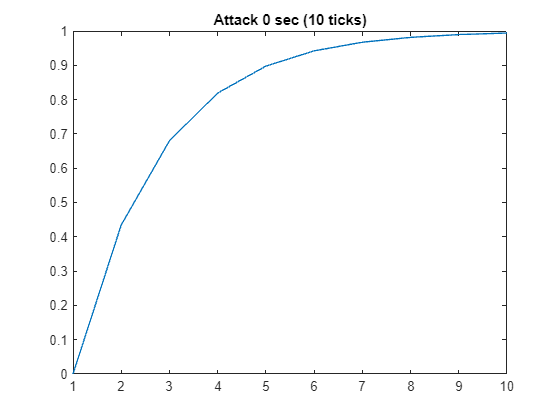

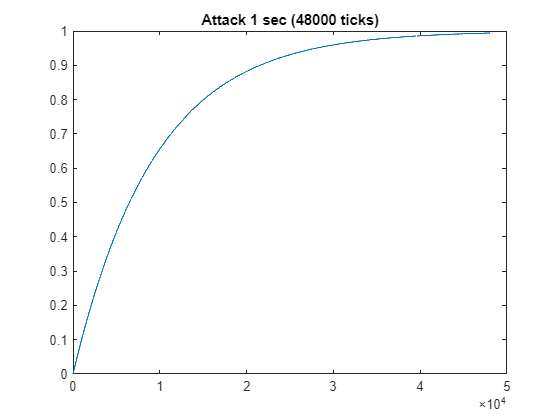

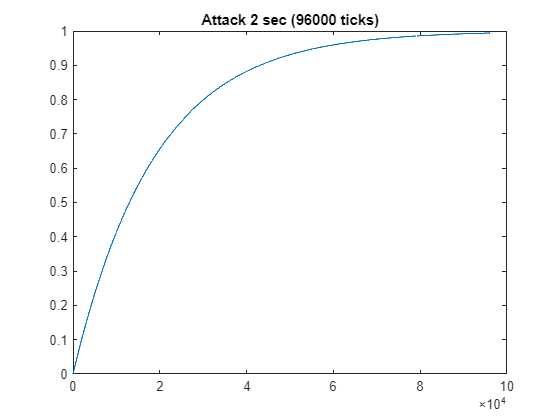

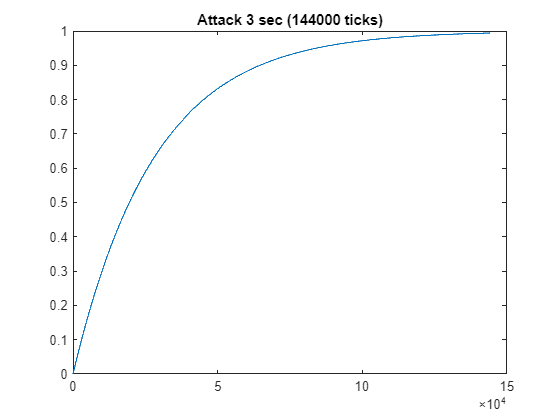

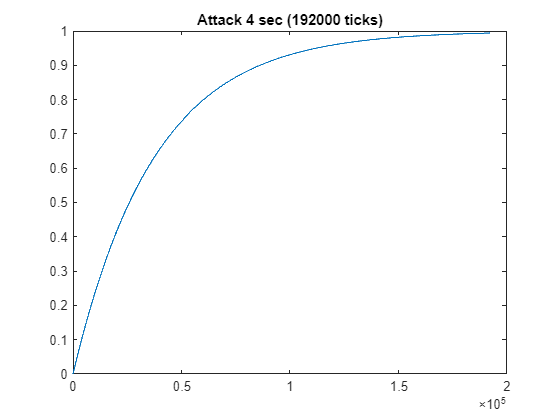

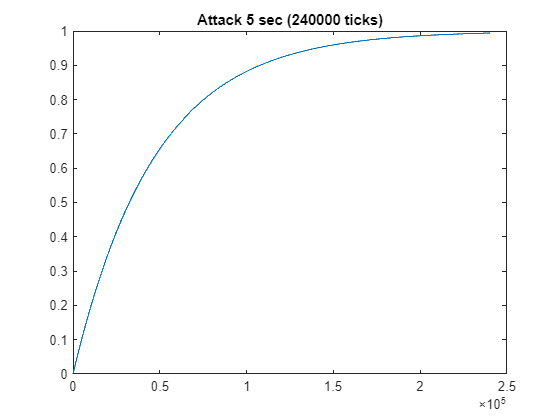

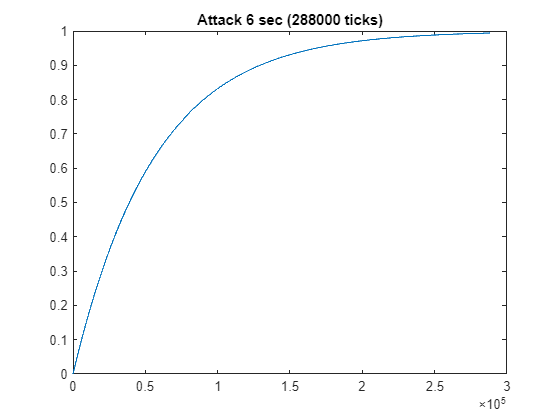

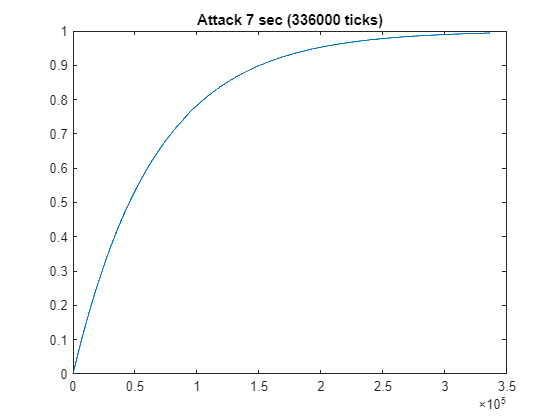

for atk_sec = 0:10
    max_tick = max(atk_min, sampling_freq * atk_sec);
    ticks = linspace(0, max_tick, max_tick);
    tau = tau1(24, max_tick, db_loss(3, 1), 1);
    figure;
    xlabel('tick');
    ylabel('amplitude');
    plot(cincr1(ticks, tau, 1, max_tick));
    title(['Attack ', int2str(atk_sec), ' sec (', int2str(max_tick), ' ticks)']);
end

COMMON FUNCTIONS TODO (yeah I know it's a bad practice)

function ai = db_loss(dbs, max_amp)
    ai = max_amp * power(10, -dbs / 20);
end
function y = cincr0(t, tau, max_amp)
    y = single(max_amp * (1 - exp(-t/tau)));
end
function y = cincr1(t, tau, max_amp, steps)
    if (t > steps)
        y = max_amp;
    else
        y = cincr0(t, tau, max_amp);
    end
end
function y = tau0(tick, A, Amax)
    y = - tick / log(1 - A/Amax);
end
function y = tau1(t_percent, atk, A, Amax)
    tick = t_percent * atk / 100;
    y = tau0(tick, A, Amax);
end